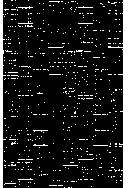

clc;clear

name_exp={ '01_00' '01_45' '01_90' '01_135' '01_180' '01_225' '01_270' '01_315'};
SF_active_all_train=[];
SF_active_all_test=[];
SF_active_all=[];
N_data=10; % samples used for train
Out_train=[];
Out_test=[];
load('SF_active_all_0.mat')
TR1=sum(SF_active_all_0,2);
TR_ind=find(TR1==0);
for si=1:8
    name_2=['csdata_' name_exp{1,si} '.mat'];
    load(name_2)
    TR1=find(sum(SF_active)==0);
    SF_active(:,TR1)=[];
    SF_active(SF_active>0)=1;
    SF_active(TR_ind,:)=[];
    cl=randperm(15-length(TR1));
    rand_cl{1,si}=cl;              
    SF_active_train=SF_active(:,cl(1:N_data));     % split into train and test
    SF_active_test=SF_active(:,cl(N_data+1:end));
    
    SF_active_all=[SF_active_all SF_active];
    SF_active_all_num_train(1,si)=N_data;  % train
    SF_active_all_train=[SF_active_all_train SF_active_train];
    Out_train=[Out_train si*ones(1,SF_active_all_num_train(1,si))];
    
    SF_active_all_num_test(1,si)=15-N_data-length(TR1); % test
    SF_active_all_test=[SF_active_all_test SF_active_test];
    Out_test=[Out_test si*ones(1,SF_active_all_num_test(1,si))];
end
SF_active_all_num=SF_active_all_num_train+SF_active_all_num_test;
TR1=find(sum(SF_active_all_train,2)==0);
SF_active_all_train(TR1,:)=[];

figure; imshow(SF_active_all,'Border','tight')

Type = 'naiveBayes';
Class_train=[]; Class_test=[];
SF_active_all_num_cum=cumsum(SF_active_all_num);
SF_cum=[0 SF_active_all_num_cum];
SF_cum(end)=[];

select_train=[];
select_test=[];
for ci=1:8
    Class_train=[Class_train ci*ones(1,N_data)];
    Class_test=[Class_test ci*ones(1,SF_active_all_num_test(ci))];
end

ResultStruct=[];
Cell_num_T=[10 20:20:180 188];
Exp_num=100;

for cell_i=1:length(Cell_num_T)
    fprintf('cell num: %d \n',Cell_num_T(cell_i))
    Cell_num_0=Cell_num_T(cell_i);  % max 196
    Cell_index=[];
    select_train=[];
    select_test=[];
    for exp_i=1:Exp_num
        if Cell_num_0~=Cell_num_T(end)
            Cell_index=single([Cell_index; randperm(Cell_num_0,Cell_num_0)]);
        else
            Cell_index=single([Cell_index; 1:Cell_num_0]);
        end
        TR_train=[];
        TR_test=[];
        for ci=1:8
            TR1=randperm(SF_active_all_num(ci),SF_active_all_num(ci))+SF_cum(ci);
            TR_train=single([TR_train TR1(1:N_data)]);
            TR_test=single([TR_test TR1(N_data+1:end)]);
        end
        select_train=single([select_train; TR_train]);
        select_test=single([select_test ; TR_test]);
    end
    ResultStruct(cell_i).Cell_index=Cell_index;
    ResultStruct(cell_i).select_train=select_train;
    ResultStruct(cell_i).select_test=select_test;
    
    % mean or max
    [ca,cb]=size(select_test);
    Resut_test_max=zeros(ca,cb);
    Resut_test_mean=zeros(ca,cb);
    result_naive=0*select_test;
    Train_num_cum=cumsum(SF_active_all_num_train);
    Train_num_cum=[0 Train_num_cum];
    
    for exp_i=1:ca  % 4000
        NB_train_data=SF_active_all(Cell_index(exp_i,:),select_train(exp_i,:));
        NB_test_data= SF_active_all(Cell_index(exp_i,:),select_test(exp_i,:));
        cell_prob=zeros(Cell_num_T(cell_i),8);
        for ci=1:8
            %             cell_prob(:,ci)=mean(NB_train_data(:,Train_num_cum(ci)+1:Train_num_cum(ci+1)),2);
            cell_prob(:,ci)=sum(NB_train_data(:,Train_num_cum(ci)+1:Train_num_cum(ci+1)),2);
            cell_prob(:,ci)=(cell_prob(:,ci)+1)/(SF_active_all_num_train(ci)+2);
        end
        delta=0.05;
        cell_prob(cell_prob==0)=delta;
        cell_prob(cell_prob==1)=1-delta;
        Out_train_cs = SF_naive_V4( cell_prob, NB_test_data);
        result_naive(exp_i,:)=Out_train_cs;
    end
    
    Result_test_all=[];
    Result_test_stat=zeros(8,3);
    for ci=1:8
        TR1=find(Class_test==ci);
        TR2=result_naive(:,TR1);
        TR3=0*TR2;
        TR3(TR2==ci)=1;
        TR4=sum(TR3,2)/SF_active_all_num_test(ci);
        Result_test_all=[Result_test_all TR4];
        Result_test_stat(ci,:)=[mean(TR4) std(TR4) length(TR4)];
    end
    ResultStruct(cell_i).Result_test_all=Result_test_all;
    ResultStruct(cell_i).Result_test_stat=Result_test_stat;
end

cell num: 10 
cell num: 20 
cell num: 40 
cell num: 60 
cell num: 80 
cell num: 100 
cell num: 120 
cell num: 140 
cell num: 160 
cell num: 180 
cell num: 188 


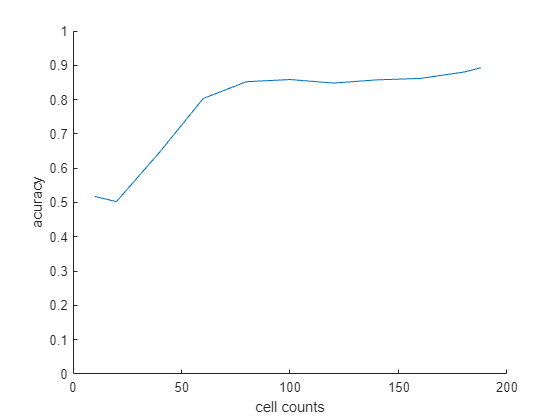

dataname=['Decoding_' Type '_' num2str(N_data) '.mat'];
save(dataname)

%%
AccPlot=[];
for cell_i=1:length(Cell_num_T)
    TR1=ResultStruct(cell_i).Result_test_all;
    TR2=mean(TR1,2);
    AccPlot=[AccPlot; ...
           Cell_num_T(cell_i) mean(TR2) std(TR2) length(TR2)];
end
figure
hold on
plot(AccPlot(:,1),AccPlot(:,2))
ylim([0 1])
xlabel('cell counts')
ylabel('acuracy')

supporting functions

function [ Out_train_cs ] = SF_naive_V4( cell_prob, NB_test_data)
%UNTITLED2 Summary of this function goes here
%   Detailed explanation goes here
Prob_1_train=cell_prob;
Prob_0_train=1-Prob_1_train;
[ca,cb]=size(NB_test_data);   % ca=cell  cb=samples
N_class=8; 
Prob_train_cs=ones(cb,N_class);
Prob_train_01=ones(cb,N_class);
Out_train_cs=[];
Out_traincs_prob=zeros(3,N_class);
for ci=1:cb
    TR1=NB_test_data(:,ci);
    for cj=1:N_class
        TR1_1=find(TR1==1);
        TR1_0=find(TR1==0);
        Prob_train_cs(ci,cj)=sum(log(Prob_1_train(TR1_1,cj)))+ sum(log(prod(Prob_0_train(TR1_0,cj))));
    end
    Prob_max=find(Prob_train_cs(ci,:)==max(Prob_train_cs(ci,:))); 
    if length(Prob_max)>1
        TR1=randperm(length(Prob_max),1);
        Out_train_cs=[Out_train_cs Prob_max(TR1)];
%          Out_train_cs=[Out_train_cs -1];
    else
         Out_train_cs=[Out_train_cs Prob_max];
    end
end

end



